clear all;
clc;

## Loading data

addpath("data");
% Loading data.
collect_time_table;

**Setup Model Parameters**

% Precentage of data used as training data.
modelParameter.trainingSize = 0.7;
% Index of RESPONSE variable in data array.
modelParameter.responseIndex = 1;

## Initial visualization

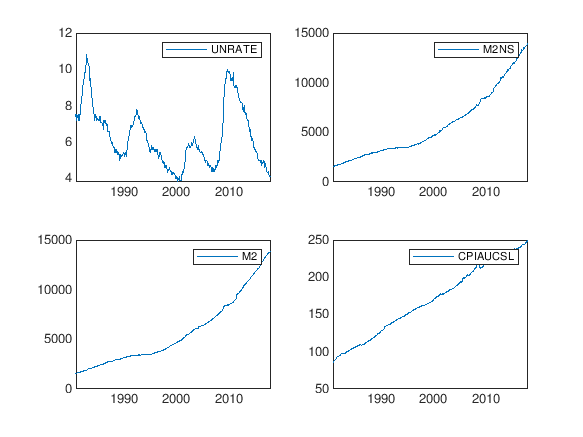

num_plot = length(names);
plot_size = ceil(sqrt(num_plot));
for i = 1:num_plot
    subplot(plot_size, plot_size, i);
    plot(data_tt.DATE, (data_ar(i, :)), 'LineWidth', 1.2);
    legend(names{i});
end

## Creating data sets

totalSize = height(data_tt);

numTimeStepsTrain = floor(...
    totalSize * modelParameter.trainingSize);

% Training Data for X.
x_ar = data_ar;
y_ar = data_tt.UNRATE';  % Response Data Y.

% Indexing, DATA(dataIndex, timeStep)

XTrain = x_ar(:, ...
    (1:numTimeStepsTrain));

YTrain = y_ar(1, ...
    (2:numTimeStepsTrain + 1));

XTest = x_ar(:, ...
    (numTimeStepsTrain + 1: end - 1));

YTest = y_ar(1, ...
    numTimeStepsTrain + 2: end);

## Standardize data (Mean Normalization)

mu = mean(XTrain, 2);
sig = std(XTrain, 0, 2);

XTrain = (XTrain - mu) ./ sig;
XTest = (XTest - mu) ./ sig;

YTrain = (YTrain - mean(YTrain)) ./ std(YTrain);


$$x_i := \frac{x_i - \overline{x}}{s_x}$$


## Setup neural network

inputSize = 4;
numResponses = 1;

numHiddenUnits.lstm1 = 256;
numHiddenUnits.lstm2 = 32;
numHiddenUnits.fc1 = 128;
numHiddenUnits.fc2 = 32;

layers = [...
	sequenceInputLayer(inputSize, "Name", "Input layer")
	lstmLayer(numHiddenUnits.lstm1, "Name", "LSTM layer 1")
	lstmLayer(numHiddenUnits.lstm2, "Name", "LSTM layer 2")
	fullyConnectedLayer(numHiddenUnits.fc1, "Name", "FC layer 1")
	fullyConnectedLayer(numResponses, "Name", "Output layer")
	regressionLayer
	];

layers2 = [...
	sequenceInputLayer(inputSize, "Name", "Input layer")
	lstmLayer(numHiddenUnits.lstm1, "Name", "LSTM layer 1")
	fullyConnectedLayer(numHiddenUnits.fc1, "Name", "FC layer 1")
	fullyConnectedLayer(numResponses, "Name", "Output layer")
	regressionLayer
	];

opts = trainingOptions(...
	"adam",...
	"MaxEpochs", 750, ...
	"GradientThreshold", 100, ...
	"InitialLearnRate", 0.05, ...
	"LearnRateSchedule", "piecewise", ...
	"LearnRateDropPeriod", 250, ...
	"LearnRateDropFactor", 0.5, ...
        "MiniBatchSize", 36, ...
	"Verbose", 0, ...
	"Plot", "training-progress");

## Training

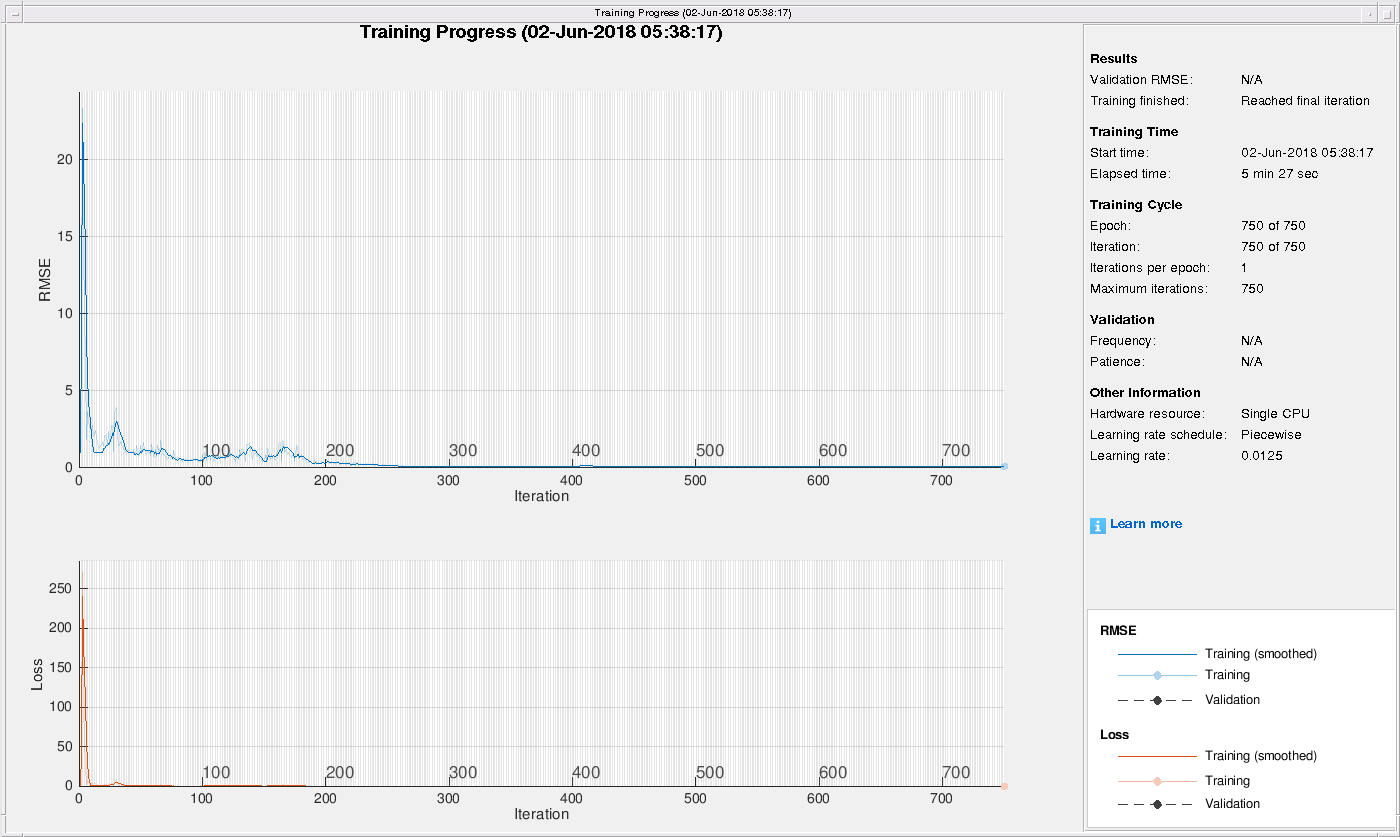

net = trainNetwork(...
	XTrain, ...
	YTrain, ...
	layers2, ...
	opts);

## Predicting

net = predictAndUpdateState(net, XTrain);

YPred = [];

net = predictAndUpdateState(net, XTrain);
YPred = [];

numTimeStepsTest = length(XTest);

for i = 1:numTimeStepsTest
	[net, YPred(1, i)] = predictAndUpdateState(net, XTest(:, i));
end

net = predictAndUpdateState(net, XTrain);

% [net, YPred] = predictAndUpdateState(net, cache);

% for i = 2:numTimeStepsTest
% 	[net, YPred(1, i)] = predictAndUpdateState(net, YPred(1, i-1));
% end

% Unstandardize result
YPred = sig(1) * YPred + mu(1);

rmse = sqrt(mean(YPred - YTest) .^ 2);

YTrain = sig(1) * YTrain + mu(1);

## Visualize

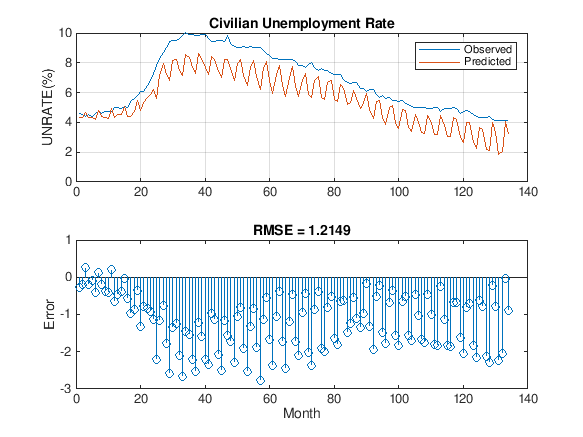

figure
subplot(2, 1, 1)
plot(YTest, "-", "LineWidth", 1.25)
hold on
plot(YPred, "-", "LineWidth", 1.25)
grid on
hold off
legend(["Observed" "Predicted"])
ylabel("UNRATE(%)")
title("Civilian Unemployment Rate")

subplot(2, 1, 2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)